# Übung 1

## 1.1 Vorbereitung

Stellen Sie durch zwei geeignete Matlab-Befehle sicher, dass

- der Workspace initialisiert ist,

- alle Figures (Diagrammfenster) geschlossen sind und

- die Darstellung der Ergebnisse 'compact', also ohne zusätzliche Leerzeilen erfolgt.

close all
clear all
format compact

Im Folgenden ergänzen/erweitern Sie dieses Script. Sofern nicht anders angegeben, unterdrücken Sie die Ergebnisausgabe (Strichpunkt am Zeilenende). Wenn Sie alle Übungsaufgaben bearbeitet haben, publizieren ('publishen') Sie das Skript als PDF.

## 1.2 Vektoren, statischer Größe

Erzeugen Sie einen Vektor *n* mit natürlichen Zahlen von 0 bis 99. Verwenden Sie hierzu die Matlab-Syntax zur Erzeugung von Vektoren.

n = [0:1:99]

n =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


Erzeugen Sie die Variable *N* und weisen Sie dieser Variablen die Länge (Zahl der Elemente) von *n* als Wert zu.

N = numel(n)

N = 100

Erzeugen Sie nun den Vektor *x*, indem sie den Vektor *n* mit dem (konstanten) Faktor 2 pi / *N* skalieren.

x = n * ( 2 * pi / N )

x =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221    1.8850    1.9478    2.0106    2.0735    2.1363    2.1991    2.2619    2.3248    2.3876    2.4504    2.5133    2.5761    2.6389    2.7018    2.7646    2.8274    2.8903    2.9531    3.0159    3.0788


Berechnen Sie aus dem Vektor x den Vektor *s* = sin(*x*)

s = sin(x)

s =          0    0.0628    0.1253    0.1874    0.2487    0.3090    0.3681    0.4258    0.4818    0.5358    0.5878    0.6374    0.6845    0.7290    0.7705    0.8090    0.8443    0.8763    0.9048    0.9298    0.9511    0.9686    0.9823    0.9921    0.9980    1.0000    0.9980    0.9921    0.9823    0.9686    0.9511    0.9298    0.9048    0.8763    0.8443    0.8090    0.7705    0.7290    0.6845    0.6374    0.5878    0.5358    0.4818    0.4258    0.3681    0.3090    0.2487    0.1874    0.1253    0.0628


Bestimmen sie das Maximum und das Minimum von *s*. Bei welchen Indizes treten diese Werte auf? Welche Werte enthalten die Vektoren *n* und *x* bei diesen Indizes? Lassen Sie diese Werte ausgeben.

min_s_indexes = find(s == min(s))

min_s_indexes = 76

min_s_values = s(min_s_indexes)

min_s_values = -1


max_s_indexes = find(s == max(s))

max_s_indexes = 26

max_s_values = s(max_s_indexes)

max_s_values = 1

Verwenden Sie nun die Funktion linspace() zur Erzeugung des Vektors *y*. *y* soll 100 Elemente von 0 bis 2 pi enthalten. Berechnen Sie aus diesem Vektor die Sinuswerte *t* = sin(*y*).

y = linspace(0, 2*pi)

y =          0    0.0635    0.1269    0.1904    0.2539    0.3173    0.3808    0.4443    0.5077    0.5712    0.6347    0.6981    0.7616    0.8251    0.8885    0.9520    1.0155    1.0789    1.1424    1.2059    1.2693    1.3328    1.3963    1.4597    1.5232    1.5867    1.6501    1.7136    1.7771    1.8405    1.9040    1.9675    2.0309    2.0944    2.1579    2.2213    2.2848    2.3483    2.4117    2.4752    2.5387    2.6021    2.6656    2.7291    2.7925    2.8560    2.9195    2.9829    3.0464    3.1099


t = sin(y)

t =          0    0.0634    0.1266    0.1893    0.2511    0.3120    0.3717    0.4298    0.4862    0.5406    0.5929    0.6428    0.6901    0.7346    0.7761    0.8146    0.8497    0.8815    0.9096    0.9341    0.9549    0.9718    0.9848    0.9938    0.9989    0.9999    0.9969    0.9898    0.9788    0.9638    0.9450    0.9224    0.8960    0.8660    0.8326    0.7958    0.7557    0.7127    0.6668    0.6182    0.5671    0.5137    0.4582    0.4009    0.3420    0.2817    0.2203    0.1580    0.0951    0.0317


Bestimmen sie auch von *t* das Maximum und das Minimum. Bei welchen Indizes treten hier diese Werte auf? Welche Werte enthalten die Vektoren *n* und *y* bei diesen Indizes? Lassen Sie diese Werte ausgeben.

min_t_indexes = find(t == min(t))

min_t_indexes = 75

min_t_values = t(min_t_indexes)

min_t_values = -0.9999


max_t_indexes = find(t == max(t))

max_t_indexes = 26

max_t_values = t(max_t_indexes)

max_t_values = 0.9999


n_values_at_min_t_indexes = n(min_t_indexes)

n_values_at_min_t_indexes = 74

y_values_at_min_t_indexes = y(min_t_indexes)

y_values_at_min_t_indexes = 4.6965

Erklären Sie das Zustandekommen der unterschiedlichen Ergebnisse!

Kommentar:

## 1.3 Vektoren, dynamischer Größe

Hier geht es darum, Vektoren zu erzeugen, deren Länge a priori nicht bekannt ist: Beispiel: Gesucht werden die ganzzahligen Teiler einer Zahl *z*. Ist *z* eine Primzahl, so gibt es keine Teiler außer 1 und *z*. Ist *z* nicht prim und beliebig groß, wird es beliebig viele Teiler geben. Die tatsächliche Zahl ist also vor der Verarbeitung nicht bekannt.

Suchen sie die ganzzahligen Teiler von *z*, indem Sie in einer (for-) Schleife probeweise durch ansteigende Ganzzahlen *t* dividieren. Geht die Division ohne Rest auf, ist *t* ein Teiler von *z*. Den Divisionsrest von *z*/_t_ berechnet Ihnen die modulo-Funktion ( mod(*z*,_t_) ). Die ermittelten Teiler von *z* speichern Sie im Vektor *tz* ab. Lassen Sie *tz* für eine beliebige Zahl *z* ( 100 < *z* < 10000, *z* nicht prim ) ausgeben.

%z = 10;
z = 100;
%z = 37;
next_storage = 1;

for i = 1:z
    if mod(z, i) == 0
        tz{next_storage} = i;
        next_storage = next_storage + 1;
    end    
end

% output if not prime, not prime if more than 2 divisors
if (numel(tz) > 2)
    tz
else
    disp('Prime Number! Not displaying diviors!');
end

tz = 1×9 cell array
    {[1]}    {[2]}    {[4]}    {[5]}    {[10]}    {[20]}    {[25]}    {[50]}    {[100]}

Das erste, respektive letzte Element des Vektors *tz* sind 1 und *z*. Entfernen Sie diese beiden Elemente vom Vektor *tz* und speichern Sie das Ergebnis im Vektor *tz2*. Zeigen Sie auch diesen Vektor an (das letzte Element eines Vektors hat den Index 'end').

tz2 = tz(2:end-1)

tz2 = 1×7 cell array
    {[2]}    {[4]}    {[5]}    {[10]}    {[20]}    {[25]}    {[50]}

## 1.4 Produkte von Vektoren

Gegeben ist der Zeilenvektor *zv*, sowie der Spaltenvektor *sv* = *zv*':

zv = (1:1:3)

zv =      1     2     3


sv = transpose(zv)

sv =      1
     2
     3


Es seien

h1 = sv * zv

h1 =      1     2     3
     2     4     6
     3     6     9


h2 = h1 ^2

h2 =     14    28    42
    28    56    84
    42    84   126


h3 = h1.^2

h3 =      1     4     9
     4    16    36
     9    36    81


h4 = zv  * sv

h4 = 14

h5 = zv .* zv

h5 =      1     4     9


h6 = zv .^ zv

h6 =      1     4    27


h7 = h1 + 1

h7 =      2     3     4
     3     5     7
     4     7    10


h8 = h1 + h1

h8 =      2     4     6
     4     8    12
     6    12    18


h9 = 1./ h1

h9 =     1.0000    0.5000    0.3333
    0.5000    0.2500    0.1667
    0.3333    0.1667    0.1111


Kommentieren Sie die Ergebnisse *h1* bis *h6*:

% h1: performs a matrix multiplication hence creates a matrix

% h2: performs h1*h1, so multiplies h1 with itself, matrix to the power of
% 2

% h3: multiplies each individual element of h1 by the scalar 2

% h4: Multiplies two vectors. The dimensions are: [1x3][3x1] = [1x1]

% h5: The dot operator multiplizes individual elements of the same vector
% with itself

% h6: power of each individual element (dot operator) with itself

h7: Elementweise Addition von 1

h8: Elementweise Addition

h9: Elementweiser Kehrwert

## 1.5 Matrizen

Erzeugen Sie die Matrix a so, dass Sie aus den Vektoren *a1* bis *a4* besteht. Geben Sie die Matrix *a* und deren Determinante aus.

a1 = [1 2 3 4]

a1 =      1     2     3     4


a2 = [5 6 7 8]

a2 =      5     6     7     8


a3 = [9 10 11 12]

a3 =      9    10    11    12


a4 = [13 14 15 16]

a4 =     13    14    15    16



a = [a1; a2; a3; a4]

a =      1     2     3     4
     5     6     7     8
     9    10    11    12
    13    14    15    16



d = det(a)

d = 6.2123e-30

Wie müsste man formulieren, wenn *a1* bis *a4* die Spaltenvektoren der Matrix sein sollen? Geben Sie auch hierfür die Matrix *a* und deren Determinante aus.

a1 = [1; 2; 3; 4]

a1 =      1
     2
     3
     4


a2 = [5; 6; 7; 8]

a2 =      5
     6
     7
     8


a3 = [9; 10; 11; 12]

a3 =      9
    10
    11
    12


a4 = [13; 14; 15; 16]

a4 =     13
    14
    15
    16



a = [a1 a2 a3 a4]

a =      1     5     9    13
     2     6    10    14
     3     7    11    15
     4     8    12    16



d = det(a)

d = 0

## 1.6 Initialisierte Vektoren/Matrizen

Zeigen Sie, anhand der Matrix *h1*, dass die Funktion zeros() das neutrale Element bzgl. der Addition von Matrizen erzeugt. Kommentieren Sie Ihr Vorgehen und das Ergebnis.

% create 3x3 matrix with arbitrary test data
m1 = [1 2 3; 4 5 6; 7 8 9]

m1 =      1     2     3
     4     5     6
     7     8     9



% create 3x3 matrix filled with zeros
m2 = zeros(3)

m2 =      0     0     0
     0     0     0
     0     0     0



% apply the neutral element. Matrix m1 is unchanged and copied into m3.
m3 = m1 + m2

m3 =      1     2     3
     4     5     6
     7     8     9


Kommentar:

% Das Ergebnis der Addition ist die Matrix selbst, d.h. zeros(5) ist das
% neutrale Element bzgl. der Addition.

Zeigen Sie, anhand der Matrix *h1*, dass die Funktion eye(5,5) das neutrale Element bzgl. der Multiplikation von Matrizen erzeugt. Kommentieren Sie Ihr Vorgehen und das Ergebnis.

I = eye(3)

I =      1     0     0
     0     1     0
     0     0     1



result = h1 * I

result =      1     2     3
     2     4     6
     3     6     9


Kommentar:

% Das Ergebnis der Multiplikation ist die Matrix selbst, d.h. zeros(5) ist
% das neutrale Element bzgl. der Addition.

## 1.7 Rechnen mit Matrizen

Skalieren Sie den Vektor *s* aus Aufgabe mit 0.5 und addieren Sie 0.5. Speichern Sie das Ergebnis im Vektor *s2*.

s

s =          0    0.0628    0.1253    0.1874    0.2487    0.3090    0.3681    0.4258    0.4818    0.5358    0.5878    0.6374    0.6845    0.7290    0.7705    0.8090    0.8443    0.8763    0.9048    0.9298    0.9511    0.9686    0.9823    0.9921    0.9980    1.0000    0.9980    0.9921    0.9823    0.9686    0.9511    0.9298    0.9048    0.8763    0.8443    0.8090    0.7705    0.7290    0.6845    0.6374    0.5878    0.5358    0.4818    0.4258    0.3681    0.3090    0.2487    0.1874    0.1253    0.0628


s2 = s.* 0.5

s2 =          0    0.0314    0.0627    0.0937    0.1243    0.1545    0.1841    0.2129    0.2409    0.2679    0.2939    0.3187    0.3423    0.3645    0.3853    0.4045    0.4222    0.4382    0.4524    0.4649    0.4755    0.4843    0.4911    0.4961    0.4990    0.5000    0.4990    0.4961    0.4911    0.4843    0.4755    0.4649    0.4524    0.4382    0.4222    0.4045    0.3853    0.3645    0.3423    0.3187    0.2939    0.2679    0.2409    0.2129    0.1841    0.1545    0.1243    0.0937    0.0627    0.0314


s3 = arrayfun(@(x) x+0.5, s2)

s3 =     0.5000    0.5314    0.5627    0.5937    0.6243    0.6545    0.6841    0.7129    0.7409    0.7679    0.7939    0.8187    0.8423    0.8645    0.8853    0.9045    0.9222    0.9382    0.9524    0.9649    0.9755    0.9843    0.9911    0.9961    0.9990    1.0000    0.9990    0.9961    0.9911    0.9843    0.9755    0.9649    0.9524    0.9382    0.9222    0.9045    0.8853    0.8645    0.8423    0.8187    0.7939    0.7679    0.7409    0.7129    0.6841    0.6545    0.6243    0.5937    0.5627    0.5314


Kehren Sie im Vektor *s2* die Reihenfolge der Elemente 25:75 um ( Funktion wrev() ).

idx = [25 75];
s2 = s2([1:min(idx)-1, max(idx):-1:min(idx), max(idx)+1:100])

s2 =          0    0.0314    0.0627    0.0937    0.1243    0.1545    0.1841    0.2129    0.2409    0.2679    0.2939    0.3187    0.3423    0.3645    0.3853    0.4045    0.4222    0.4382    0.4524    0.4649    0.4755    0.4843    0.4911    0.4961   -0.4990   -0.4961   -0.4911   -0.4843   -0.4755   -0.4649   -0.4524   -0.4382   -0.4222   -0.4045   -0.3853   -0.3645   -0.3423   -0.3187   -0.2939   -0.2679   -0.2409   -0.2129   -0.1841   -0.1545   -0.1243   -0.0937   -0.0627   -0.0314   -0.0000    0.0314


Multiplizieren *s2* mit ones(100,1) so, dass Sie am Ende eine 100x100 Matrix erhalten, die *s2* spaltenweise enthält.

ones_vec = ones(100, 1)

ones_vec =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


mat1 = ones_vec * s2

mat1 =          0    0.0314    0.0627    0.0937    0.1243    0.1545    0.1841    0.2129    0.2409    0.2679    0.2939    0.3187    0.3423    0.3645    0.3853    0.4045    0.4222    0.4382    0.4524    0.4649    0.4755    0.4843    0.4911    0.4961   -0.4990   -0.4961   -0.4911   -0.4843   -0.4755   -0.4649   -0.4524   -0.4382   -0.4222   -0.4045   -0.3853   -0.3645   -0.3423   -0.3187   -0.2939   -0.2679   -0.2409   -0.2129   -0.1841   -0.1545   -0.1243   -0.0937   -0.0627   -0.0314   -0.0000    0.0314
         0    0.0314    0.0627    0.0937    0.1243    0.1545    0.1841    0.2129    0.2409    0.2679    0.2939    0.3187    0.3423    0.3645    0.3853    0.4045    0.4222    0.4382    0.4524    0.4649    0.4755    0.4843    0.4911    0.4961   -0.4990   -0.4961   -0.4911   -0.4843   -0.4755   -0.4649   -0.4524   -0.4382   -0.4222   -0.4045   -0.3853   -0.3645   -0.3423   -0.3187   -0.2939   -0.2679   -0.2409   -0.2129   -0.1841   -0.1545   -0.1243   -0.0937   -0.0627   -0.0314   -0.0000  

Benutzen Sie die Funktion imshow() um das Ergebnis Ihrer Berechnung als Grauwertbild darzustellen.

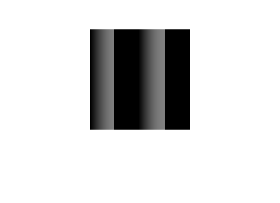

imshow(mat1)